clc;close all;clear;clear drawArm;
addpath('inc\')
load("data/system_parameters.mat");

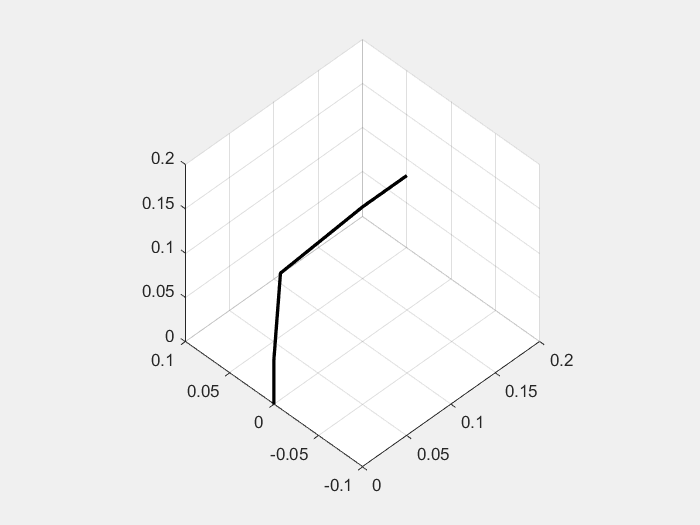

R = 0.032;
psi = pi/2;
point = [0.15;0;0.12]+R*[0;cos(psi);sin(psi)];
q = invKin([0 0 0],point,"ElbowUp",p);
T = fwdKin(q,p);

h = figure();
drawArm(T,h);


J = jac(T.T40(1:3,4),T)

J =    -0.0000   -0.1020   -0.0093   -0.0000
    0.1500    0.0000    0.0000    0.0000
         0    0.1500    0.1425    0.0500
         0    0.0000    0.0000    0.0000
         0   -1.0000   -1.0000   -1.0000
    1.0000    0.0000    0.0000    0.0000



v4 = [0;-3e-3;0];

% v4_4 = T.T40(1:3,1:3)\v4;% 
% w4 = [0;0;-v4_4(3)/norm(T.T40(1:2,4))]

w4 = [0;0;-3e-3/T.T40(1,4)] % since the tip is on the x-axis, it is trivial to find w_z = v_y/o_4,x

w4 =          0
         0
   -0.0200



Xi = [v4;w4];

q_d = invVel(J,Xi)

q_d =    -0.0200
    0.0000
   -0.0000
   -0.0000
